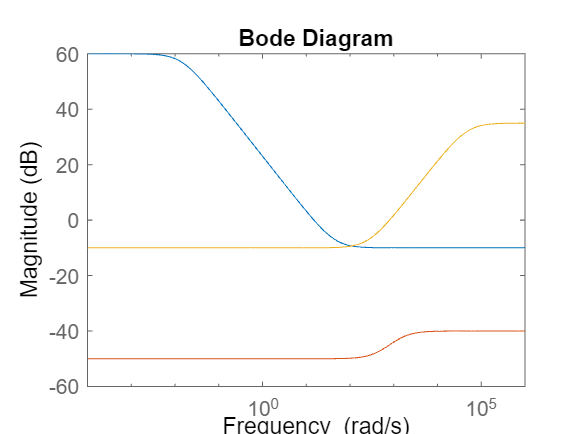

[Gss, G] = FoundTF(90);

W1 = makeweight(db2mag(60),[15 db2mag(0)],db2mag(-10)); 
W2 = makeweight(db2mag(-50),[800 db2mag(-45)],db2mag(-40)); 
W3 = makeweight(db2mag(-10),[800 db2mag(0)],db2mag(35));
figure()
bodemag(W1Theta,W2,W3)


%Peso de las perturbaciones
Wp      = makeweight(1,[10 0.1],0.01);
%Peso Error Posicion
W1Theta      = W1;
%Peso Error velocidad
W1Omega      = W1;
%Peso Señal de Control PWM
W2PWM      = W2;
%Peso Salida Ángulo Theta
W3Theta      = W3;
%Peso Salida velocidad Omega
W3Omega      = W3;
%Peso del ruido
Wn      = 0.001;
%Matriz A
A       = Gss.A;
%Matriz B
B       = Gss.B;
%L observador
L       = [1.25; 2];
%Integrador
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



PosIntegrator = (1/s);
VelIntegrator = (1/s);

systemnames     = 'G A B L PosIntegrator VelIntegrator Wp Wn W1Theta W1Omega W2PWM W3Theta W3Omega';
inputvar        = '[per; n; rTheta; rOmega; uPWM]';
outputvar       = '[W1Theta; W1Omega; W2PWM; W3Theta; W3Omega; -G - Wn + rTheta;-VelIntegrator - Wn + rOmega]';
input_to_G   = '[-Wp + uPWM]';
input_to_A      = '[PosIntegrator; VelIntegrator]';
input_to_B      = '[uPWM]';
input_to_L      = '[G - PosIntegrator]';
input_to_PosIntegrator = '[A(1,1)+B(1,1)+L(1,1)]';
input_to_VelIntegrator = '[A(2,1)+B(2,1)+L(2,1)]';
input_to_Wn     = '[n]';
input_to_Wp     = '[per]';
input_to_W1Theta     = '[-G - Wn + rTheta]';
input_to_W1Omega     = '[-VelIntegrator - Wn + rOmega]';
input_to_W2PWM     = '[uPWM]';
input_to_W3Theta     = '[G]';
input_to_W3Omega     = '[VelIntegrator]';

sysnom_ic = sysic;

Index in position 1 exceeds array bounds. Index must not exceed 1.

Error in sysic>LOCALgaino (line 608)
   ff(i+startloc,sysloc+out(i)) = ff(i+startloc,sysloc+out(i)) + gain;

Error in sysic (line 270)
               ff = LOCALgaino(out,gains(j),ff,location,sysloc);